# ***Battery State of Charge Estimation using Feedforward Deep Neural Network***

## Ghani Amri Rabbani, Ary Syahriar, Dwi Astharini, Haris Al-Qodri Maarif, Ahmad Husin Lubis, Danny Mokhammad Gandana

**Instructions for Downloading and Running the Script**

- Download raw datasets of Samsung battery from Mendeley Data page [https://data.mendeley.com/datasets/9xyvy2njj3/1](https://data.mendeley.com/datasets/9xyvy2njj3/1) 

- After downloading all the files including this one, unzip the file to a folder, do not modify the folder structure.

- Navigate to the folder with "DSP_FDNN_Samsung_LiIon_Battery.mlx".

- Open and run "DSP_FDNN_Samsung_LiIon_Battery.mlx".

- The matlab script should run without any modification, if there is an issue it's likely due to the testing and training data not being in the expected place.

- If required to modify the script, follow the comprehensive step-by-step in README file.

- The script is set by default to train for 1000 epochs with early-stopping method and to repeat the training 3 times. This should take 5-30 minutes to execute.

 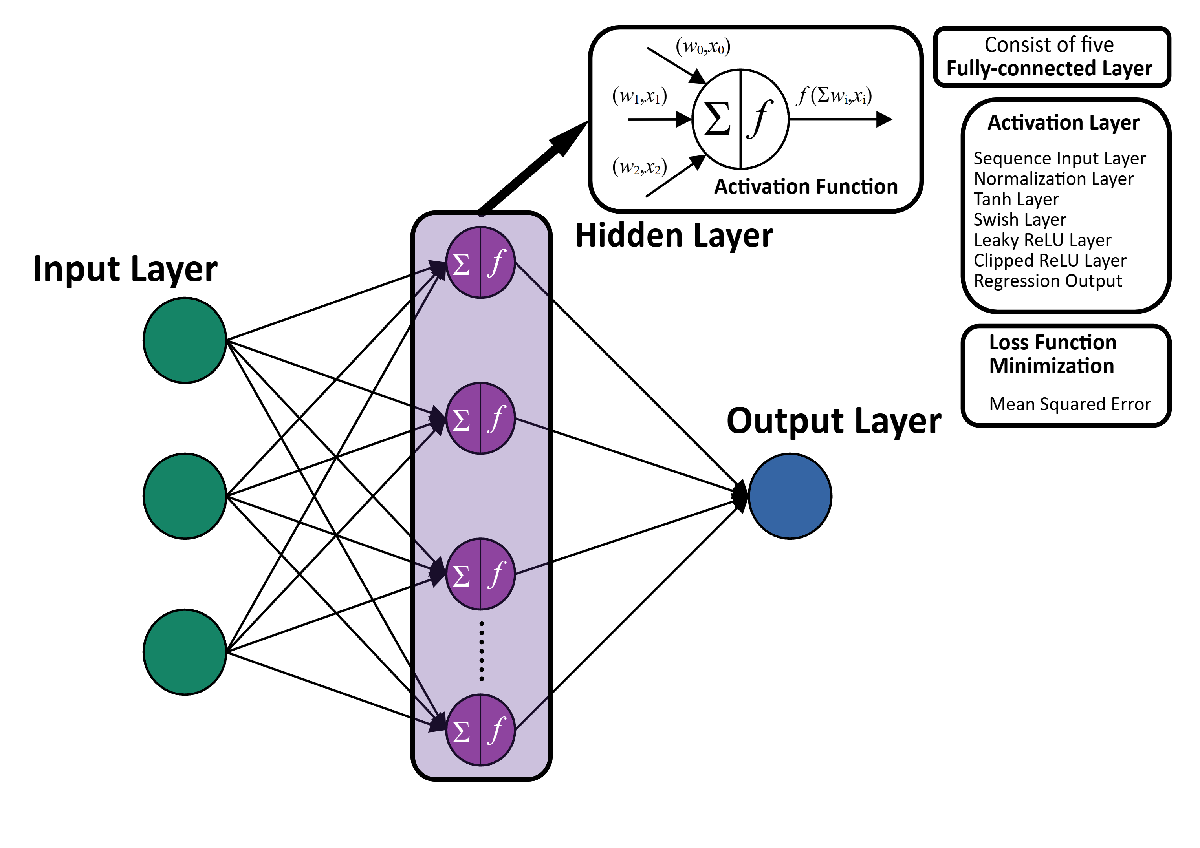

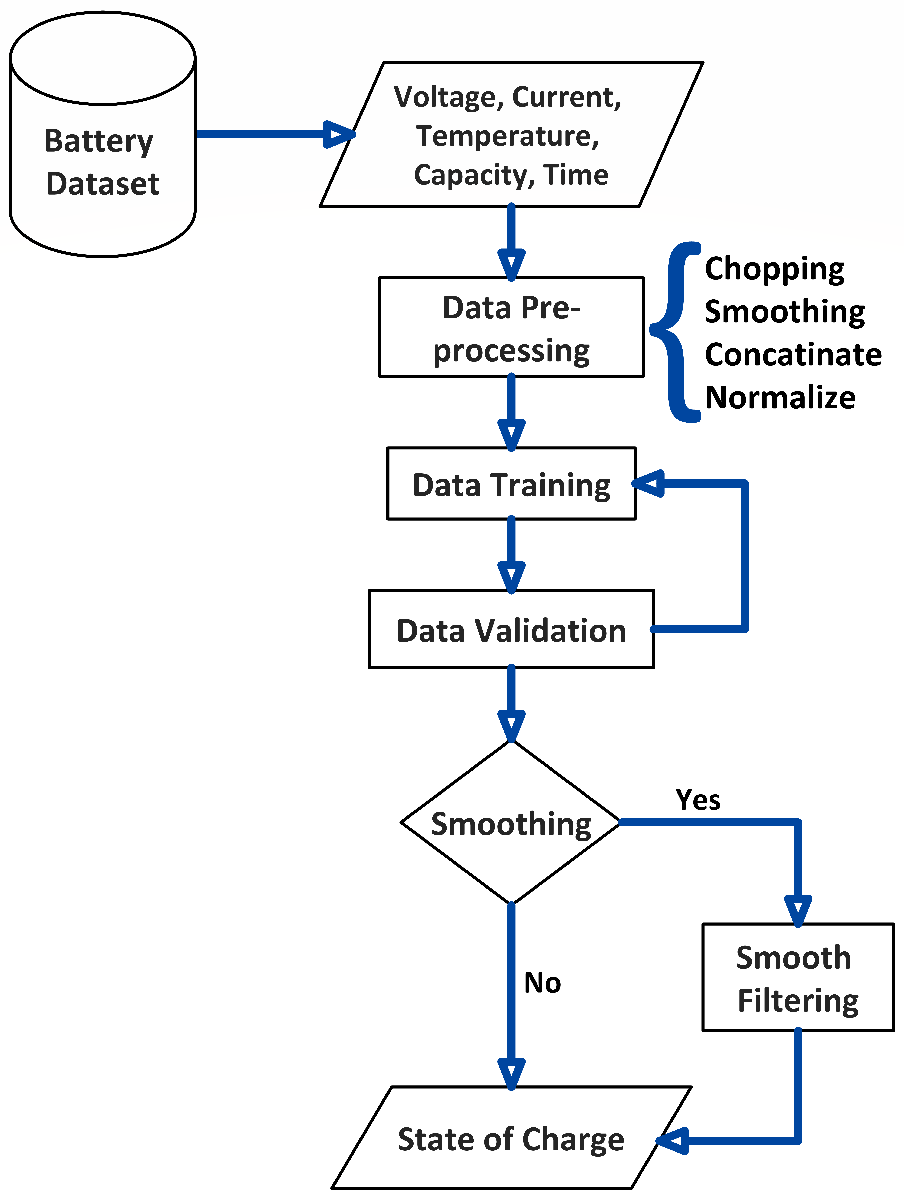

The main goal of this script is to provide a study of battery State of Charge (SOC) estimation using the Feedforward Deep Neural Network (FDNN) reinforced with Digital Signal Processing (DSP) technique. The following script analyzes the battery's SOC and terminal voltage (Vt) during a driving cycle using a fully-connected layer of FDNN reinforced with DSP filtering technique such as Gaussian, Savitzky-Golay, and Robust Local Regression with considering effects of battery surface temperature.

Each file in folder "Prepared Dataset" named in abbreviation of U.S. EPA driving cycle in order: HWFET, UDDS, and US06 which contain specific operating temperatures.

Run each driving cycle at the same operating ambient temperature to get a different results as shown in the paper. 

clc;
close all;
clearvars;
fclose all;

**Add the Dataset File name**

Replace "**FileName.zip**" by the file name you want to use. Note: The zip file need to have "**Train**"  and "**Test**" separate folders

filename ="Battery Datasets\Preprocessed Dataset\Samsung@US06.zip"; % Add the Dataset File name
outputFolder = fullfile(tempdir,"Samsung@US06");% The temporary location and name where the training data unzipped
unzip(filename,outputFolder);

**Add the location** in ('...') where the data of each iteration will be stored as it will save multiple models at each epoch (see"CheckpointPath" on the training parameter);

mkdir("Data folder")

NET_Path = "Data folder"; %select the Datafolder created in the next popup window to allow storing the data each iteration
NET_Path=uigetdir('','Select folder to store data from each training iteration'); 

## Create Datastore datasets - Training and Testing

Necessary when working with large collections of data

(Check Matlab Help for "datastore")

folderTrain = fullfile(outputFolder,"Train");
fdsPredictorTrain = fileDatastore(folderTrain, ...
    'ReadFcn',@load, ...
    'IncludeSubfolders',true);  %Is a datastore, for the training dataset, which is a repository for collections of data that are too large to fit in memory. 

folderTest = fullfile(outputFolder,"Test");
fdsPredictorTest = fileDatastore(folderTest, ...
    'ReadFcn',@load, ...
    'IncludeSubfolders',true); % Is a datastore, for the Testing dataset, which is a repository for collections of data that are too large to fit in memory 

preview(fdsPredictorTrain)
preview(fdsPredictorTest)
folderYTrain = fullfile(outputFolder,"Train");
fdsObjectiveTrain = fileDatastore(folderYTrain, ...
    'ReadFcn',@load, ...
    'IncludeSubfolders',true);% Is a datastore for the objective function, in this case SOC reference data for the training dataset. 

folderYTest = fullfile(outputFolder,"Test");
fdsObjectiveTest = fileDatastore(folderYTest, ...
    'ReadFcn',@load, ...
    'IncludeSubfolders',true);% Is a datastore for the objective function, in this case SOC reference data for the testing dataset.

preview(fdsObjectiveTrain)
preview(fdsObjectiveTest)

## Transform and Combine Data set

RR=readall(fdsPredictorTrain);    % read all training data files
numObservations = numel(RR);
for i=1:numObservations
    sequence = RR{i};  %combine training data set files into one structure. 
    sequenceLengths(i) = size(sequence.X,2);
end

## Mini-Batch Size

AugmentedDataTrain = 1;
AugmentedDataTest = 1;
NumberOfMinibatches = 1; % If the dataset doesn't fit the memmory it'e necessary to increase the number of MiniBatches. Need to be a integer number 1 or >1.
miniBatchSize = round(numObservations*NumberOfMinibatches) % Size of Mini-batches 

sequenceLength = max(sequenceLengths)%Max length of the training dataset files if the files are not in the same length, this will determine the amount of padding on the shorter files. If all files have the same lenght, there will be no padding .
sequenceLength = round(sequenceLength*AugmentedDataTrain);

RRR=readall(fdsPredictorTest); % read all Test data files
numObservationsY = numel(RRR);
for i=1:numObservationsY
    sequence = RRR{i}; %Combine Test data set files into one structure.
    sequenceLengthsY(i) = size(sequence.X,2);
end
sequenceLengthY= max(sequenceLengthsY) %Max length of the objective function of the training dataset (SOC or Ah)
sequenceLengthY= round(sequenceLengthY*AugmentedDataTest);

RRTest=readall(fdsPredictorTest);
numObservationsTest = numel(RRTest);

## Transforming Datastore dataset

Padding will be used if the files have different lengths, the padding function is set to repeat the last part of the shorter files to match the size of the longest file in the dataset (valid only when there are multiple files in the dataset). Is preferable to avoid as much padding as possible.

fdsObjectiveTrain = transform(fdsObjectiveTrain,@(data) padSequenceY(data,sequenceLength)); % Padding function - Objective function Training Dataset
fdsObjectiveTest = transform(fdsObjectiveTest,@(data) padSequenceY(data,sequenceLengthY)); % Padding function - Objective function Testing Dataset
ObjectiveTest = readall(fdsObjectiveTest); %Objective function Test dataset, this is only to help manipulate the dataset for ploting and calculate the Errors.

tdsTrain = transform(fdsPredictorTrain,@(data) padSequence(data,sequenceLength)); % Padding function - Training Dataset
tdsTest = transform(fdsPredictorTest,@(data) padSequence(data,sequenceLengthY));  % Padding function - Testing Dataset
PredictorTest = readall(tdsTest);% Predictors test dataset 

To input both the predictors and Objectives from both datastores into a deep learning network, combine them using the `combine` function.

cdsTrain = combine(tdsTrain,fdsObjectiveTrain);
cdsTest = combine(tdsTest,fdsObjectiveTest);

Preview the combined datastore.  The first element corresponds to the "Predictors". The second element corresponds to the "Objective".

preview(cdsTest)
preview(cdsTrain)

Specify batch size and number of batches

batchSize = 128;  % Adjust as needed
numBatches = ceil(numObservations / batchSize);

## Creating GPU Device Environment

gpuDeviceObj = gpuDevice;

Loop through batches for training using GPU

for batchIdx = 1:numBatches
    % Read a batch of data from the Datastore
    batch = read(cdsTrain);
    predictors = batch{1}; % Extract predictors
    objectives = batch{2}; % Extract objectives
    
    % Convert the batch to GPU arrays
    predictorsTrainOnGPU = gpuArray(single(predictors)); % Assuming predictors are numeric
    objectivesTrainOnGPU = gpuArray(single(objectives)); % Assuming objectives are numeric
    
    % Perform deep learning operations using predictorsOnGPU and objectivesOnGPU
    % For example, train your neural network, perform predictions, etc.
    
    % Clear GPU memory (optional, depending on memory requirements)
    % reset(gpuDeviceObj);
end

Loop through batches for testing/validation

for batchIdx = 1:numBatches
    % Read a batch of data from the Datastore
    batch = read(cdsTest);
    predictors = batch{1}; % Extract predictors
    objectives = batch{2}; % Extract objectives
    
    % Convert the batch to GPU arrays
    predictorsTestOnGPU = gpuArray(single(predictors)); % Assuming predictors are numeric
    objectivesTestOnGPU = gpuArray(single(objectives)); % Assuming objectives are numeric
    
    % Perform deep learning operations using predictorsOnGPU and objectivesOnGPU
    % For example, evaluate your trained network on the validation/test set
    
    % Clear GPU memory (optional, depending on memory requirements)
    % reset(gpuDeviceObj);
end

## Validation dataset

X = predictorsTestOnGPU; % X predictors Validation dataset
Y = objectivesTestOnGPU; % Objective function "Y == SOC" for the Validation dataset

## Define NN Network Architecture

Define the NN network architecture.  

## Specify NN training parameter

Number of outputs (**SOC**)

numResponses = 1;

Number of inputs features (**Voltage, Current, Temperature**)

numFeatures = 3;

Number of hidden units **'N'**, where each hidden unit for FNN represents a Neuron.

numHiddenUnits = 20;

Number of **Epochs**

Epochs = 1000;

**Learning rate schedule**

LearnRateSchedule = 'piecewise';

Inital Learning Rate. very important paramater

InitialLearnRate = 0.01;

Number of epochs for dropping the learning rate

LearnRateDropPeriod = 1000;

Factor for dropping the learning rate, ex.: reduce to 10% of the current learning rate at every 'LearnRateDropPeriod

LearnRateDropFactor = 0.1;

Validate the model at each Iterations when values is equal to 1.

validationFrequency = 10;

Select the amount the training process will be repeated 

repeat = 3;

## **FDNN - Structure**

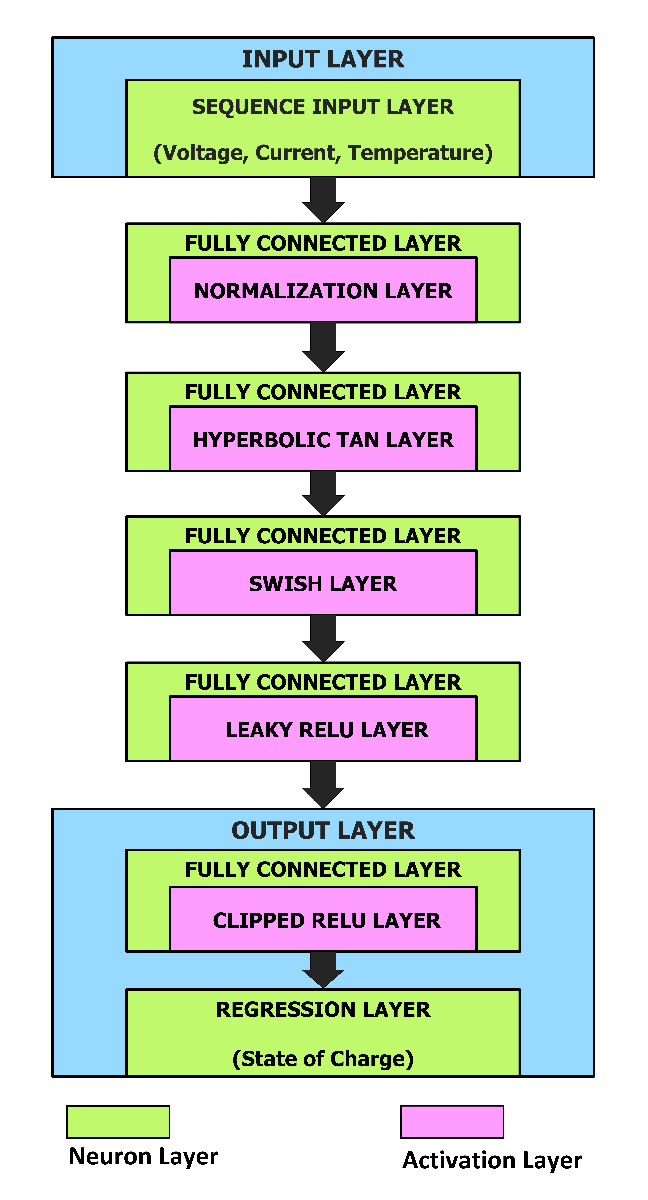

layers = [sequenceInputLayer(numFeatures,"Normalization","zerocenter")
    fullyConnectedLayer(numHiddenUnits)
    layerNormalizationLayer
    fullyConnectedLayer(numHiddenUnits)
    tanhLayer
    fullyConnectedLayer(numHiddenUnits)
    swishLayer
    fullyConnectedLayer(numHiddenUnits)
    leakyReluLayer
    fullyConnectedLayer(numResponses)
    clippedReluLayer(1)
    regressionLayer];

options = trainingOptions('adam',...% choose 'adam' optimizer or 'rmsprop' optimizer
    'ExecutionEnvironment','gpu',...% Select GPU if you works on computer with Nvidia GPU
    'L2Regularization',1e-6,... % choose L1 regularization (Lasso) or L2 regularization (Ridge)
    'Epsilon',1e-8,...
    'MaxEpochs',Epochs,...
    'SquaredGradientDecayFactor',0.999,... % tuning for rmsprop and/or adam optimizer
    'GradientDecayFactor',0.9,... %tuning for adam optimizer
    'GradientThreshold',Inf,...
    'GradientThresholdMethod','l2norm',...
    'LearnRateSchedule',LearnRateSchedule,...
    'InitialLearnRate',InitialLearnRate,...
    'LearnRateDropPeriod',LearnRateDropPeriod,...
    'LearnRateDropFactor',LearnRateDropFactor,...
    'ValidationData',{X,Y},...
    'ValidationFrequency',validationFrequency,...
    'ValidationPatience',5,...
    'MiniBatchSize',miniBatchSize,...
    'Shuffle','never',...
    'Verbose',1,...
    'BatchNormalizationStatistics','moving',...
    'ResetInputNormalization', 1,...
    'OutputNetwork','best-validation-loss',...
    'Plots','training-progress',...
    'CheckpointPath', NET_Path); % to save each trained model during the training process, if necessary it can be "commented-out" and will only the last model will be available to be save.

## Train the FNN network with the specified training options.

for i=1:repeat
    net = trainNetwork(cdsTrain,layers,options);

# **Test the Network**

**The following section is used to calcultae the MAX, MAE, RMS errors of the test dataset and to plot the corresponding SOC of Test dataset after the training process **

    N=50; % To remove the first 'N' and last 'NN' datapoints to compensate the lack of previous data, which wouldn't normally occur in a real life xEV application
    NN=50;
    
    YT = readall(fdsObjectiveTest);
    XT = readall(fdsPredictorTest);

    X_T=[];Y_Test=[];X_Test=[];Y_T=[];
    Error_Test=[];
    Nets{i} = net; % save the last trained model at the end of each repeat

    Y_Pred_n20degC = predict(net,XT{6,1}.X,'MiniBatchSize',miniBatchSize);
    Y_Pred_n10degC = predict(net,XT{5,1}.X,'MiniBatchSize',miniBatchSize);
    Y_Pred_0degC = predict(net,XT{1,1}.X,'MiniBatchSize',miniBatchSize);
    Y_Pred_10degC = predict(net,XT{2,1}.X,'MiniBatchSize',miniBatchSize);
    Y_Pred_25degC = predict(net,XT{3,1}.X,'MiniBatchSize',miniBatchSize);
    Y_Pred_40degC = predict(net,XT{4,1}.X,'MiniBatchSize',miniBatchSize);

**This section is the smooth filtering method being applied. To have an unfiltered results, add a comment "%" to the code at each code line.**

    Y_Pred_n20degC = smoothdata(Y_Pred_n20degC,"gaussian",15000);
    Y_Pred_n20degC = smoothdata(Y_Pred_n20degC,"rloess","SmoothingFactor",0.9);
    Y_Pred_n10degC = smoothdata(Y_Pred_n10degC,"gaussian",12000);
    Y_Pred_n10degC = smoothdata(Y_Pred_n10degC,"rloess","SmoothingFactor",0.9);
    Y_Pred_0degC = smoothdata(Y_Pred_0degC,"gaussian",5000);
    Y_Pred_0degC = smoothdata(Y_Pred_0degC,"rloess","SmoothingFactor",0.9);
    Y_Pred_10degC = smoothdata(Y_Pred_10degC,"gaussian",9000);
    Y_Pred_10degC = smoothdata(Y_Pred_10degC,"rloess","SmoothingFactor",0.9);
    Y_Pred_25degC = smoothdata(Y_Pred_25degC,"gaussian",6000);
    Y_Pred_25degC = smoothdata(Y_Pred_25degC,"rloess","SmoothingFactor",0.9);
    Y_Pred_40degC = smoothdata(Y_Pred_40degC,"gaussian",7000);
    Y_Pred_40degC = smoothdata(Y_Pred_40degC,"rloess","SmoothingFactor",0.9);

**This section is calculating the relative error of estimation.**

    Error_Test_n20degC = Y_Pred_n20degC-XT{6,1}.Y;
    Error_Test_n10degC = Y_Pred_n10degC-XT{5,1}.Y;
    Error_Test_0degC = Y_Pred_0degC-XT{1,1}.Y;
    Error_Test_10degC = Y_Pred_10degC-XT{2,1}.Y;
    Error_Test_25degC = Y_Pred_25degC-XT{3,1}.Y;
    Error_Test_40degC = Y_Pred_40degC-XT{4,1}.Y;
    
    E_Test_RMSE_n20degC{i} = sqrt(mean((Error_Test_n20degC).^2))*100; %SOC Test dataset root mean square error
    E_Test_MAE_n20degC{i} = mae(Error_Test_n20degC)*100; %SOC Test dataset Mean abs error 
    E_Test_MAX_n20degC{i} = max(abs(Error_Test_n20degC)*100); %max SOC error of Test dataset

    E_Test_RMSE_n10degC{i} = sqrt(mean((Error_Test_n10degC).^2))*100; %SOC Test dataset root mean square error
    E_Test_MAE_n10degC{i} = mae(Error_Test_n10degC)*100; %SOC Test dataset Mean abs error 
    E_Test_MAX_n10degC{i} = max(abs(Error_Test_n10degC)*100); %max SOC error of Test dataset
    
    E_Test_RMSE_10degC{i} = sqrt(mean((Error_Test_10degC).^2))*100; %SOC Test dataset root mean square error
    E_Test_MAE_10degC{i} = mae(Error_Test_10degC)*100; %SOC Test dataset Mean abs error 
    E_Test_MAX_10degC{i} = max(abs(Error_Test_10degC)*100); %max SOC error of Test dataset
    
    E_Test_RMSE_0degC{i} = sqrt(mean((Error_Test_0degC).^2))*100; %SOC Test dataset root mean square error
    E_Test_MAE_0degC{i} = mae(Error_Test_0degC)*100; %SOC Test dataset Mean abs error 
    E_Test_MAX_0degC{i} = max(abs(Error_Test_0degC)*100); %max SOC error of Test dataset
    
    E_Test_RMSE_25degC{i} = sqrt(mean((Error_Test_25degC).^2))*100; %SOC Test dataset root mean square error
    E_Test_MAE_25degC{i} = mae(Error_Test_25degC)*100; %SOC Test dataset Mean abs error 
    E_Test_MAX_25degC{i} = max(abs(Error_Test_25degC)*100); %max SOC error of Test dataset

    E_Test_RMSE_40degC{i} = sqrt(mean((Error_Test_40degC).^2))*100; %SOC Test dataset root mean square error
    E_Test_MAE_40degC{i} = mae(Error_Test_40degC)*100; %SOC Test dataset Mean abs error 
    E_Test_MAX_40degC{i} = max(abs(Error_Test_40degC)*100); %max SOC error of Test dataset

 end

RMSE_SUMMARY = ['-20degC_RMSE',E_Test_RMSE_n20degC;'-10degC_RMSE',E_Test_RMSE_n10degC;'0degC_RMSE',E_Test_RMSE_0degC;'10degC_RMSE',E_Test_RMSE_10degC;'25degC_RMSE',E_Test_RMSE_25degC;'40degC_RMSE',E_Test_RMSE_40degC];
MAE_SUMMARY = ['-20degC_MAE',E_Test_MAE_n20degC;'-10degC_MAE',E_Test_MAE_n10degC;'0degC_MAE',E_Test_MAE_0degC;'10degC_MAE',E_Test_MAE_10degC;'25degC_MAE',E_Test_MAE_25degC;'40degC_MAE',E_Test_MAE_40degC];
MAX_SUMMARY = ['-20degC_MAX',E_Test_MAX_n20degC;'-10degC_MAX',E_Test_MAX_n10degC;'0degC_MAX',E_Test_MAX_0degC;'10degC_MAX',E_Test_MAX_10degC;'25degC_MAX',E_Test_MAX_25degC;'40degC_MAE',E_Test_MAE_40degC];

figure 
bar(cell2mat(RMSE_SUMMARY(:,2:end)'),'DisplayName','RMSE Results')
legend(["-20degC" "-10degC" "0degC" "10degC" "25degC" "40degC"])
ylabel("RMSE (%)")
xlabel('# Repeats')
title("Test - Estimation RMSE of HWFET (%)")
figure
bar(cell2mat(MAE_SUMMARY(:,2:end)'),'DisplayName','MAE Results')
legend(["-20degC" "-10degC" "0degC" "10degC" "25degC" "40degC"])
ylabel("MAE (%)")
xlabel('# Repeats')
title("Test - Estimation MAE of HWFET (%)")
figure
bar(cell2mat(MAX_SUMMARY(:,2:end)'),'DisplayName','MAX Results')
legend(["-20degC" "-10degC" "0degC" "10degC" "25degC" "40degC"])
ylabel("MAX (%)")
xlabel('# Repeats')
title("Test - Estimation MAX of HWFET (%)")

## Based on the best result from the above figure select the best #repeat to plot the on time domain

[Minimum_0degC, idx] = min(cell2mat(E_Test_RMSE_0degC));
SelectNet = idx;
SelectNet = 1; % Manual selection

Y_Pred_n20degC = predict(Nets{SelectNet},XT{6,1}.X,'MiniBatchSize',miniBatchSize);
Y_Pred_n10degC = predict(Nets{SelectNet},XT{5,1}.X,'MiniBatchSize',miniBatchSize);
Y_Pred_0degC = predict(Nets{SelectNet},XT{1,1}.X,'MiniBatchSize',miniBatchSize);
Y_Pred_10degC = predict(Nets{SelectNet},XT{2,1}.X,'MiniBatchSize',miniBatchSize);
Y_Pred_25degC = predict(Nets{SelectNet},XT{3,1}.X,'MiniBatchSize',miniBatchSize);
Y_Pred_40degC = predict(Nets{SelectNet},XT{4,1}.X,'MiniBatchSize',miniBatchSize);

Y_Pred_n20degC = smoothdata(Y_Pred_n20degC,"gaussian",15000);
Y_Pred_n20degC = smoothdata(Y_Pred_n20degC,"rloess","SmoothingFactor",0.9);
Y_Pred_n10degC = smoothdata(Y_Pred_n10degC,"gaussian",12000);
Y_Pred_n10degC = smoothdata(Y_Pred_n10degC,"rloess","SmoothingFactor",0.9);
Y_Pred_0degC = smoothdata(Y_Pred_0degC,"gaussian",5000);
Y_Pred_0degC = smoothdata(Y_Pred_0degC,"rloess","SmoothingFactor",0.9);
Y_Pred_10degC = smoothdata(Y_Pred_10degC,"gaussian",9000);
Y_Pred_10degC = smoothdata(Y_Pred_10degC,"rloess","SmoothingFactor",0.9);
Y_Pred_25degC = smoothdata(Y_Pred_25degC,"gaussian",6000);
Y_Pred_25degC = smoothdata(Y_Pred_25degC,"rloess","SmoothingFactor",0.9);
Y_Pred_40degC = smoothdata(Y_Pred_40degC,"gaussian",7000);
Y_Pred_40degC = smoothdata(Y_Pred_40degC,"rloess","SmoothingFactor",0.9);

Error_Test_n20degC = Y_Pred_n20degC-XT{6,1}.Y;
Error_Test_n10degC = Y_Pred_n10degC-XT{5,1}.Y;
Error_Test_0degC = Y_Pred_0degC-XT{1,1}.Y;
Error_Test_10degC = Y_Pred_10degC-XT{2,1}.Y;
Error_Test_25degC = Y_Pred_25degC-XT{3,1}.Y;
Error_Test_40degC = Y_Pred_40degC-XT{4,1}.Y;

figure
subplot(2,1,1)
hold all
plot(XT{1, 1}.Y*100,"blue",'LineWidth',1.5); 
plot(Y_Pred_n20degC*100,"red",'LineWidth',1.5);
legend(["Observed" "Predicted"])
ylabel("(SOC)")
xlabel('Time(s)')
title("SOC@-20degC of HWFET Estimation")
grid on
subplot(2,1,2)
hold all;
plot((Error_Test_n20degC)*100,"black",'LineWidth',1.5); 
legend("Error")
ylabel("(%)")
xlabel('Time(s)')
title("Error")
grid on
figure
subplot(2,1,1)
hold all;
plot(XT{2, 1}.Y*100,"blue",'LineWidth',1.5);
plot(Y_Pred_n10degC*100,"red",'LineWidth',1.5);
legend(["Observed" "Predicted"])
ylabel("(SOC)")
xlabel('Time(s)')
title("SOC@-10degC of HWFET Estimation")
grid on
subplot(2,1,2)
hold all;
plot((Error_Test_n10degC)*100,"black",'LineWidth',1.5); 
legend("Error")
ylabel("(%)")
xlabel('Time(s)')
title("Error")
grid on
figure
subplot(2,1,1)
hold all;
plot(XT{3, 1}.Y*100,"blue",'LineWidth',1.5); 
plot(Y_Pred_0degC*100,"red",'LineWidth',1.5);
legend(["Observed" "Predicted"])
ylabel("(SOC)")
xlabel('Time(s)')
title("SOC@0degC of HWFET Estimation")
grid on
subplot(2,1,2)
hold all;
plot((Error_Test_0degC)*100,"black",'LineWidth',1.5); 
legend("Error")
ylabel("(%)")
xlabel('Time(s)')
title("Error")
grid on
figure
subplot(2,1,1)
hold all;
plot(XT{4, 1}.Y*100,"blue",'LineWidth',1.5); 
plot(Y_Pred_10degC*100,"red",'LineWidth',1.5);
legend(["Observed" "Predicted"])
ylabel("(SOC)")
xlabel('Time(s)')
title("SOC@10degC of HWFET Estimation")
grid on
subplot(2,1,2)
hold all;
plot((Error_Test_10degC)*100,"black",'LineWidth',1.5);
legend("Error")
ylabel("(%)")
xlabel('Time(s)')
title("Error")
grid on
figure
subplot(2,1,1)
hold all;
plot(XT{5, 1}.Y*100,"blue",'LineWidth',1.5); 
plot(Y_Pred_25degC*100,"red",'LineWidth',1.5);
legend(["Observed" "Predicted"])
ylabel("(SOC)")
xlabel('Time(s)')
title("SOC@25degC of HWFET Estimation")
grid on
subplot(2,1,2)
hold all;
plot((Error_Test_25degC)*100,"black",'LineWidth',1.5); 
legend("Error")
ylabel("(%)")
xlabel('Time(s)')
title("Error")
grid on
figure
subplot(2,1,1)
hold all;
plot(XT{6, 1}.Y*100,"blue",'LineWidth',1.5); 
plot(Y_Pred_40degC*100,"red",'LineWidth',1.5);
legend(["Observed" "Predicted"])
ylabel("(SOC)")
xlabel('Time(s)')
title("SOC@40degC of HWFET Estimation")
grid on
subplot(2,1,2)
hold all;
plot((Error_Test_40degC)*100,"black",'LineWidth',1.5); 
legend("Error")
ylabel("(%)")
xlabel('Time(s)')
title("Error")
grid on

## Functions

The `padSequence` function pads or truncates the sequence in `data.X` to have the specified sequence length and returns the result in a 1-by-1 cell.

function sequence = padSequence(data,sequenceLength)
sequence = data.X;
[C,S] = size(sequence);

if S < sequenceLength
    N=round((sequenceLength/S)*1);
    Pad=repmat(sequence,1,N);  
    padding = Pad(:,1:sequenceLength-S);
    sequence = [sequence padding];
else
    sequence = sequence(:,1:sequenceLength);
end
sequence = {sequence};
end
function sequenceY = padSequenceY(data,sequenceLength)
sequenceY = data.Y;
[C,S] = size(sequenceY);
if S < sequenceLength
    N=round((sequenceLength/S)*1);
    Pad=repmat(sequenceY,1,N);
    padding = Pad(:,1:sequenceLength-S);
    sequenceY = [sequenceY padding];
else
    sequenceY = sequenceY(:,1:sequenceLength);
end
sequenceY = {sequenceY};
end

## Copyright Notice

This code is a modified version from the original works of *LG 18650HG2 Li-ion battery data and example Deep Neural Network Xev SOC estimator script* by Philip Kollmeyer, Carlos Vidal, Mina Naguib, Michael Skells under Creative Commons Attribution 4.0 International licence. All right reserved.

## Reference

[1] Kollmeyer, P. (2020, March 5). *LG 18650HG2 Li-ion battery data and example Deep Neural Network Xev SOC estimator script*. Mendeley Data. [https://data.mendeley.com/datasets/cp3473x7xv/3](https://data.mendeley.com/datasets/cp3473x7xv/3) 

[2] Kollmeyer, Phillip. (2020, December 24). *Samsung INR21700 30T 3AH Li-Ion Battery Data*. Mendeley Data. [https://doi.org/10.17632/9xyvy2njj3.1](https://doi.org/10.17632/9xyvy2njj3.1) 

[3] *Mathworks smoothdata*. Smooth noisy data - MATLAB. (2023). [https://www.mathworks.com/help/matlab/ref/smoothdata.html](https://www.mathworks.com/help/matlab/ref/smoothdata.html) 